[bu, mu1, mu2, mu3, obstaclePositions] = generateRandomCoordinates();
disp('bu:');

bu:


disp(bu);

     3     8



disp('mu1:');

mu1:


disp(mu1);

     6     7



disp('mu2:');

mu2:


disp(mu2);

     5     1



disp('mu3:');

mu3:


disp(mu3);

     5     2



disp('obstaclePositions:');

obstaclePositions:


disp(obstaclePositions);

     5     3
     4     8
     3     2



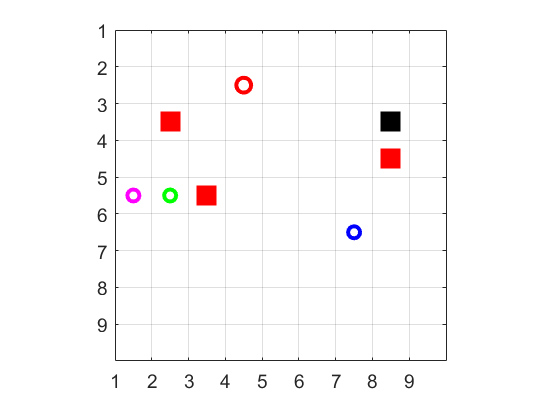


robotSimulation_setup(mu1,mu2,mu3,bu,targetPosition,obstaclePositions);

% initialize the info matrices
bu_info = zeros(gridSize);
bu_info(bu(1,1),bu(1,2)) = 4;

%ekleme başı
for i=1:size(obstaclePositions,1)
    bu_info(obstaclePositions(i,1),obstaclePositions(i,2)) = 8;
end
%ekleme sonu


a = mu1(1);
b = mu1(2);
mu1_info=zeros(gridSize);
mu1_info(a,b)=1;


%ekleme başı
for i=1:size(obstaclePositions,1)
    mu1_info(obstaclePositions(i,1),obstaclePositions(i,2)) = 8;
end
%ekleme sonu


a = mu2(1);
b = mu2(2);
mu2_info=zeros(gridSize);
mu2_info(a,b)=2;

%ekleme başı
for i=1:size(obstaclePositions,1)
    mu2_info(obstaclePositions(i,1),obstaclePositions(i,2)) = 8;
end
%ekleme sonu

a = mu3(1);
b = mu3(2);
mu3_info=zeros(gridSize);
mu3_info(a,b)=3;

%ekleme başı
for i=1:size(obstaclePositions,1)
    mu3_info(obstaclePositions(i,1),obstaclePositions(i,2)) = 8;
end
%ekleme sonu

%ekleme başı
% Your initial playgroundvisualized:

robotSimulation_setup(mu1,mu2,mu3,bu,targetPosition,obstaclePositions);



%ekleme sonu


%%%%%%%%%%%%%%%%%%%%%%%%%%%% SEARCH ALGORITM %%%%%%%%%%%%%%%%%%%%%%%

% mu: is a number between [1,3] represents the mu number
% mu_info:10x10 matrix representing the information known by mu

% Obtain the row and column of mu
[currentRow1,currentCol1] =find(mu1_info==1);
currentPosition1=[currentRow1,currentCol1];

[currentRow2,currentCol2] =find(mu2_info==2);
currentPosition2=[currentRow2,currentCol2];

[currentRow3,currentCol3] =find(mu3_info==3);
currentPosition3=[currentRow3,currentCol3];

[buRow, buCol] = find(bu_info == 4);
buPosition=[buRow,buCol];
bu = buPosition;

targetRow=targetPosition(1);
targetCol=targetPosition(2);

numberofiterations=numberofiter;

%Create empty arrays for recording the mu's locations for all time
mu1_all=cell(1,numberofiterations);
mu2_all=cell(1,numberofiterations);
mu3_all=cell(1,numberofiterations);
%set initial locations for the 1st element
mu1_all{1}=[currentRow1,currentCol1];
mu2_all{1}=[currentRow2,currentCol2];
mu3_all{1}=[currentRow3,currentCol3];

% Define possible moves (up, down, right, left)
moves = [0, 1; 0, -1; 1, 0; -1, 0];

% initialize  the trajectory matrices
trajectory_mu1 = [];
trajectory_mu2 = [];
trajectory_mu3 = [];
aimedPosition1 = [];
aimedPosition2 = [];
aimedPosition3 = [];

maxRange = gridSize/2.5;

targetisFound1 = 0;
targetisFound2 = 0;
targetisFound3 = 0;

for i=1:numberofiterations
    %Collect the data of mu past location
    unitPositions = [currentPosition1; currentPosition2; currentPosition3; buPosition];
    
    linkMatrix = checkCommunication(obstaclePositions, unitPositions, maxRange);
    [mu1_info, mu2_info, mu3_info, bu_info] = knowledgeLinkUpdater(linkMatrix,mu1_info,mu2_info,mu3_info,bu_info);
    
    % mu1 plans its move
    avoidPositions1 = [buPosition; obstaclePositions];
    [trajectory_mu1,~] = moveee(trajectory_mu1, currentPosition1, mu1_info, aimedPosition1, avoidPositions1);
    
    if isempty(trajectory_mu1)
        move_mu1 = [0 0];
    else
        move_mu1 = trajectory_mu1(1,:);
    end
    
    nextPosition1 = currentPosition1 + move_mu1;
    mu1_info(nextPosition1(1), nextPosition1(2))=7;
    
    
    % communicate again to avoid collusion
    [mu1_info, mu2_info, mu3_info, bu_info] = knowledgeLinkUpdater(linkMatrix,mu1_info,mu2_info,mu3_info,bu_info);
    
    % mu2 plans its move
    avoidPositions2 = [buPosition; obstaclePositions]; %değişti
    [trajectory_mu2,~] = moveee(trajectory_mu2, currentPosition2, mu2_info, aimedPosition2, avoidPositions2);
    
    if isempty(trajectory_mu2) 
        move_mu2 = [0 0];
    else
        move_mu2 = trajectory_mu2(1,:);
    end

    
    
       
    nextPosition2 = currentPosition2 + move_mu2;

    %ekleme başı
    if(isequal(nextPosition2,nextPosition1))
        nextPosition2 = currentPosition2; % Does stay in its place if it aims for the same position 

    end
    %ekleme sonu

    mu2_info(nextPosition2(1), nextPosition2(2))=7;
    
    % communicate again to avoid collusion
    [mu1_info, mu2_info, mu3_info, bu_info] = knowledgeLinkUpdater(linkMatrix,mu1_info,mu2_info,mu3_info,bu_info);
    
    % mu3 plans its move
    avoidPositions3 = [buPosition; obstaclePositions];
    [trajectory_mu3,~] = moveee(trajectory_mu3, currentPosition3, mu3_info, aimedPosition3, avoidPositions3);
    
    if isempty(trajectory_mu3)
        move_mu3 = [0 0];
    else
        move_mu3 = trajectory_mu3(1,:);
    end
    
    
    
    nextPosition3 = currentPosition3 + move_mu3;

    %ekleme başı
    if(isequal(nextPosition3,nextPosition2) || isequal(nextPosition3,nextPosition1) )
        nextPosition3 = currentPosition3; % Does stay in its place if it aims for the same position 

    end
    %ekleme sonu


    mu3_info(nextPosition3(1), nextPosition3(2))=7;
    
    
    %%%%%%%%
    
    % check if already at target, if so make next position current position
    if([currentPosition1(1), currentPosition1(2)] == [targetRow,targetCol])
        nextPosition1(1) = targetRow;
        nextPosition1(2) = targetCol;
        mu1_info(currentPosition1(1), currentPosition1(2))=6;
        targetisFound1 = 1;
        break
    else
        
        
        
        %Change the value of currentPosition as scanned
        mu1_info(currentPosition1(1), currentPosition1(2))=5;
        % Move to the empty location
                currentPosition1 = nextPosition1;
        %give the information of the location of where the mu is.
        mu1_info(nextPosition1(1), nextPosition1(2))=1;
        
        
        
    end
    
    % check if already at taget, if so make next position current position
    if([currentPosition2(1), currentPosition2(2)] == [targetRow,targetCol])
        nextPosition2(1) = targetRow;
        nextPosition2(2) = targetCol;
        mu2_info(currentPosition2(1), currentPosition2(2))=6;
        targetisFound2 = 1;
        break
    else
        
        
        
        %Change the value of currentPosition as scanned
        mu2_info(currentPosition2(1), currentPosition2(2))=5;
        % Move to the empty location
        currentPosition2 = nextPosition2;
        %give the information of the location of where the mu is.
        mu2_info(nextPosition2(1), nextPosition2(2))=2;
        
        
    end
    
    % check if already at target, if so make next position current position
    if([currentPosition3(1), currentPosition3(2)] == [targetRow,targetCol])
        nextPosition3(1) = targetRow;
        nextPosition3(2) = targetCol;
        mu3_info(currentPosition3(1), currentPosition3(2))=6;
        targetisFound3 = 1;
        break
    else
        
        
        %Change the value of currentPosition as scanned
        mu3_info(currentPosition3(1), currentPosition3(2))=5;
        % Move to the empty location
        currentPosition3 = nextPosition3;
        %give the information of the location of where the mu is.
        mu3_info(nextPosition3(1), nextPosition3(2))=3;
        
    end
    
    %Collect the data of mu past location
    mu1_all{i+1}=[currentPosition1(1), currentPosition1(2)];
    mu2_all{i+1}=[currentPosition2(1), currentPosition2(2)];
    mu3_all{i+1}=[currentPosition3(1), currentPosition3(2)];
    
end

targetFound = i;
sumTargetFound = sumTargetFound + targetFound;

%end
%avgTargetFound = sumTargetFound/monteCarlo;
%disp(avgTargetFound)

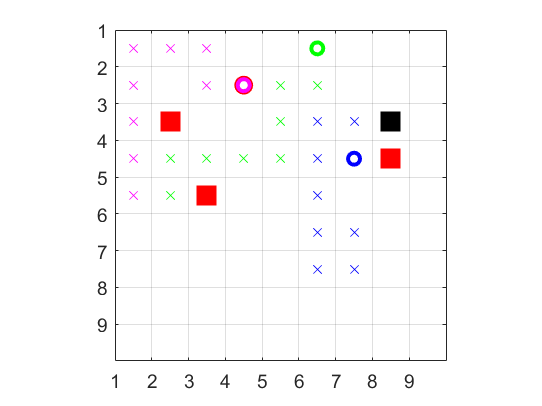

%%%%%%%%%%%%%%%%%%%%%%%%%%% DISPLAY %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% disp(mu1_info);
% disp(mu2_info);
% disp(mu3_info);
robotSimulation_vol2(mu1_all,mu2_all,mu3_all,bu,targetPosition,i,obstaclePositions)